# Regresja, interpolacja i aproksymacja danych pomiarowych 

Ten skrypt stanowi przewodnik po metodach macierzowych stosowanych do rozwiązywania układów liniowych. Obejmuje on zagadnienia takie jak **regresja, interpolacja i aproksymacja**. Użyjemy funkcji i poleceń MATLABa do rozwiązywania przykładów praktycznych na przykładzie czujnika odległości.

**Wprowadzenie**

**Regresja** liniowa jest jedną z najczęściej stosowanych metod matematycznych, używaną w takich dziedzinach jak fizyka, biologia czy uczenie maszynowe. W tym skrypcie omówimy podstawy układów liniowych i metody macierzowe ich rozwiązywania.

**Przykład regresji liniowej**

Regresja liniowa to metoda **dopasowania modelu matematycznego** do danych, który opisuje zależność między zmienną niezależną x a zmienną zależną y.

**Interpolacja** danych to metoda, która korzystając z ograniczonego zasobu danych o przebiegu funkcji potrafi wygenerować szacunkowy przebieg tej funkcji. 

Dla przykładu wykorzystamy szereg punktów pokrywających się z przebiegiem funkcji y=cos(x) i sprawdzimy dokładność interpolacji za pomocą funkcji *interp1.*

Zaczniemy od zadeklarowania zakresu od 0 do 2pi, z krokiem o pi/8.

x = 0:pi/8:2*pi;

Następnie, do zmiennej *y* przypiszemy odpowiadające wartościom *x* wartości funkcji *cos(x)*.

y = cos(x);

Kolejno wygenerujemy ostatni potrzebny parametr, a więc punkty próbkowania dla funkcji *interp1. *Dla zwiększenia częstotliwości, ustalimy krok na pi/32.

xq = 0:pi/32:2*pi;

Dalszym krokiem będzie wykorzystanie funkcji *interp1* do wygenerowania interpolacji i narysowanie na jej podstawie wykresu.

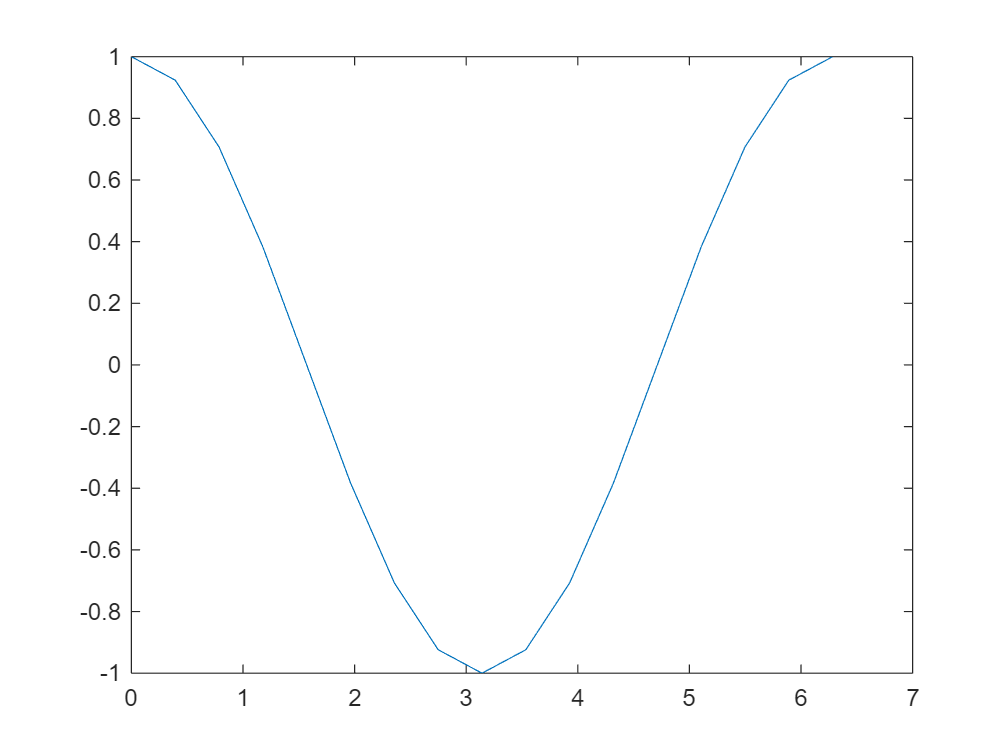

intrp = interp1(x, y, xq);
plot(xq, intrp)

Jak widać na wygenerowanym wykresie, funkcja jest zbliżona kształtem do funkcji *cosinus*, przy czym przy uważnym przyjrzeniu się można zauważyć, że jest ona złożona z połączonych ze sobą prostych. Można więc wyciągnąć prosty wniosek, że wraz ze zwiększaniem ilości punktów próbek uzyskamy wykres dużo bardziej zbliżony do rzeczywistego wykresu funkcji.

**Aproksymacja** to wygenerowanie przybliżonego rozwiązania na podstawie danych puntków. Przydaje się ona do wyznaczania linii trendu w przypadkach, kiedy ograniczony i niedokładny zbiór danych nie wyznacza idealnej funkcji, ale wskazuje konkretny kierunek przebiegu funkcji.

Zaczniemy od wygenerowania zbioru puntków od 0 do 20.

x = 0:1:20;

W następnym kroku przypiszemy do zmiennej *y *wartości funkcji 2x+1

y = 2*x + 1;

W celu oddalenia puntków od rzeczywistego przebiegu funkcji, zmienimy w sposób losowy położenie puntków na osi y.

r = randi([-5 5],1,21);
y = y + r;

W dalszej kolejności użyjemy funkcji *polyfit *do wygenerowania linii prostej uśredniającej przebieg wyznaczonych puntków, po czym narysujemy wykres zawierający punkty i prostą.

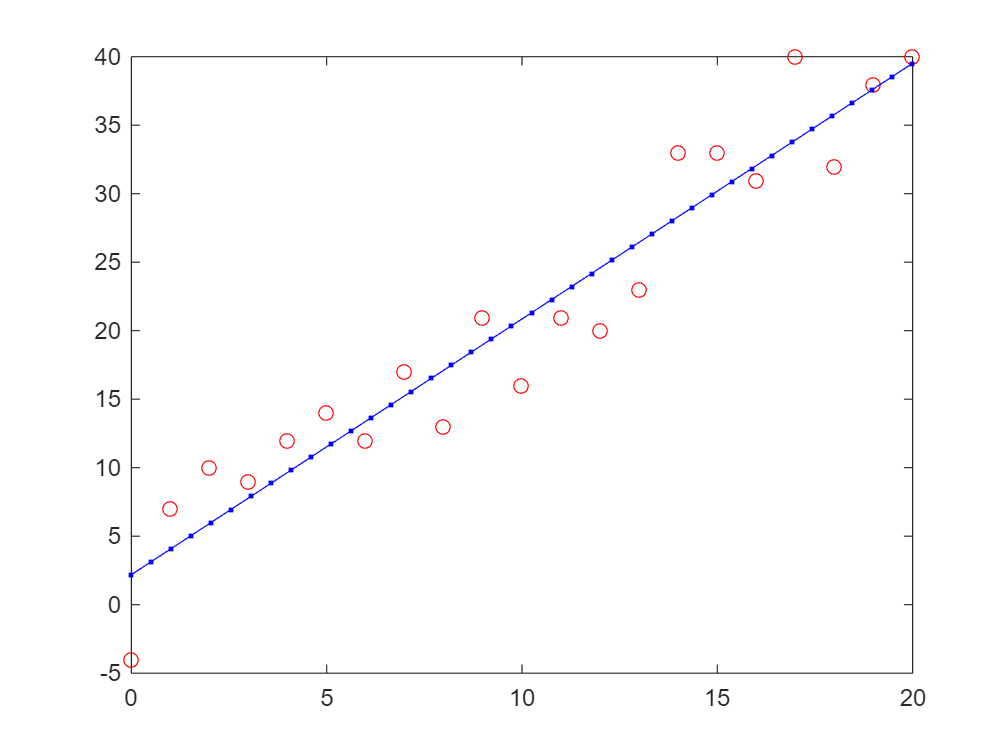

prosta = polyfit(x, y, 1);
x_fit = linspace(0,20,40);
y_fit = polyval(prosta, x_fit);
plot(x, y, 'ro', x_fit, y_fit, 'b.-')

Wykorzystanie funkcji *randi* sprawia, że każde wykonanie segmentu kodu daje inne rezultaty, dzięki czemu możemy obserwować różnice w oszacowanej funkcji. Zmiana zakresu generowanych losowo wartości z [-5 5] na szerszy lub węższy odpowiednio zmniejszy lub zwiększy dokładność generowania aproksymacji funkcji.

Rozważmy **przykład regresji liniowej**, w którym dopasowujemy linię prostą do danych. Użyjemy funkcji polyfit MATLABa, aby znaleźć najlepsze dopasowanie dla zestawu danych.

Gdy jako trzeci argument do funkcji:

% doc  polyfit

podamy wartość większą od 1, to dopasowanie funkcji do danych pomairowych odbędzie się za pomocą wielomianu. Dla stopnia wielomianu = 1: 

% Generowanie przykładowych danych
x_data = [1 2 3 4 5];
y_data = [2.2 2.8 3.6 4.5 5.1];
stopien_wielomianu = 1; 
% Oblicz współczynniki regresji liniowej (nachylenie i przesunięcie)
p = polyfit(x_data, y_data, stopien_wielomianu);

% Wyświetlenie współczynników
disp("Współczynniki regresji liniowej (nachylenie i przesunięcie):")

Współczynniki regresji liniowej (nachylenie i przesunięcie):


disp(p)

    0.7500    1.3900



**Regresja wielomianowa **

Funkcja $ \texttt{polyfit} $ znajduje współczynniki $\(a_0, a_1, \ldots, a_n\) $wielomianu:


$$
\[
y = a_n x^n + a_{n-1} x^{n-1} + \ldots + a_1 x + a_0
\]$$


`gdzie: `

`x` – wektor wartości niezależnych,

`y` – wektor wartości zależnych,

`n` – stopień wielomianu,

`p` – wektor współczynników wielomianu od najwyższego do najniższego stopnia.

stopien_wielomianu = 2; 
p2 = polyfit(x_data, y_data, stopien_wielomianu);
disp(["Współczynniki regresji wielomianem stopnia :", num2str(stopien_wielomianu)])

    "Współczynniki regresji wielomianem stopnia :"    "2"



disp(p2)

    0.0071    0.7071    1.4400



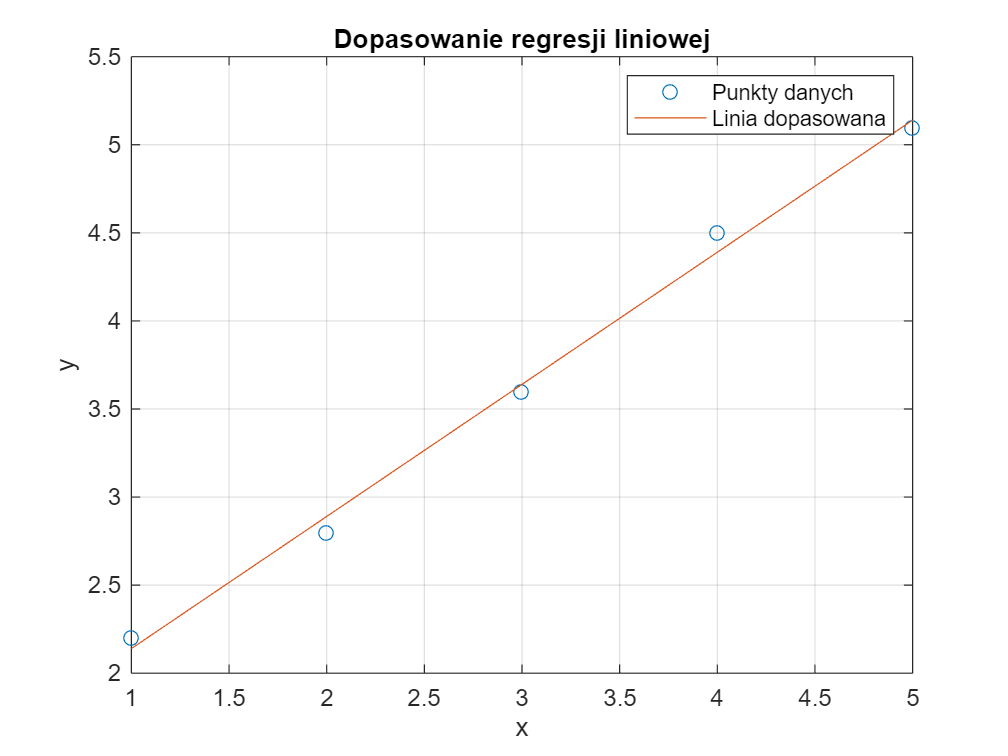


% Rysowanie danych i linii regresji
figure
plot(x_data, y_data, 'o')
hold on
plot(x_data, polyval(p, x_data), '-')
title("Dopasowanie regresji liniowej")
xlabel("x")
ylabel("y")
legend("Punkty danych", "Linia dopasowana")
grid on
hold off

Przykład Interpolacji

**Interpolacja** to metoda polegająca na **znalezieniu wartości pośrednich** między znanymi punktami danych.

Podczas ćwiczeń laboratoryjnych należy wykonać serię pomiarów za pomocą Arduino UNO i czujnia odległości, następnie wykonać aplikację, tak aby dla dowolnej wartości napięcia na wyjąsciu czujnika aplikacja wskazywała rzeczywistą odległość. Dokonać oceny dokładności wskazań dla **nieliniowej** charakteystyki głośnika. 

**Regresja i interpolacja danych z analogowego czujnika odległości**

W ćwiczeniach tych należy wykonać kalibrację analogowego czujnika odległości, używając różnych metod dostępnych w MATLAB. Celem jest przekształcenie sygnału analogowego z czujnika na odpowiadającą mu odległość za pomocą metod interpolacji i dopasowania krzywych.

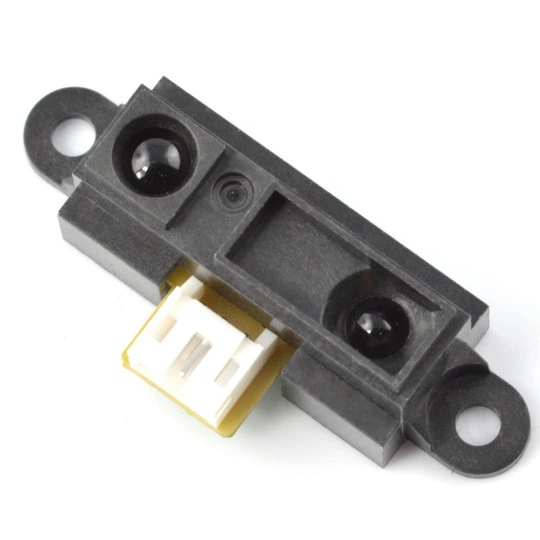    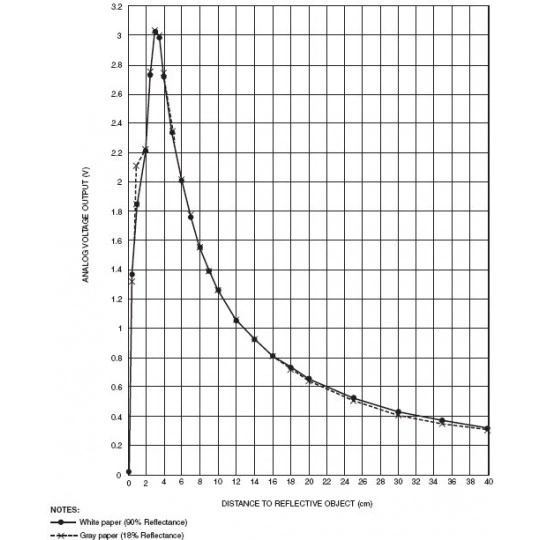 

Zdjecie oraz charaktersytyka U = f(x) czujnika odległości wykorzystanego podczas ćwiczeń laboratoryjnych.

**2. Wymagania wstępne**

Przed przystąpieniem do ćwiczeń:

- Zapoznaj się z działaniem czujników analogowych i zasady kalibracji.

- Nalezy wykorzystać mikrokontroler Arduino (jedno z wejść analogowych) i analogowy czujnik odległosci do uzyskania danych wejśiowych do laboratorium. Należy zainstalować bibliotekę do Arduino UNO.

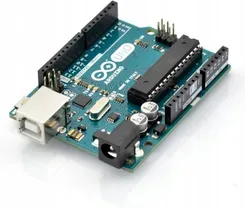

Zdjecia mikrokontrolera Arduino UNO. 

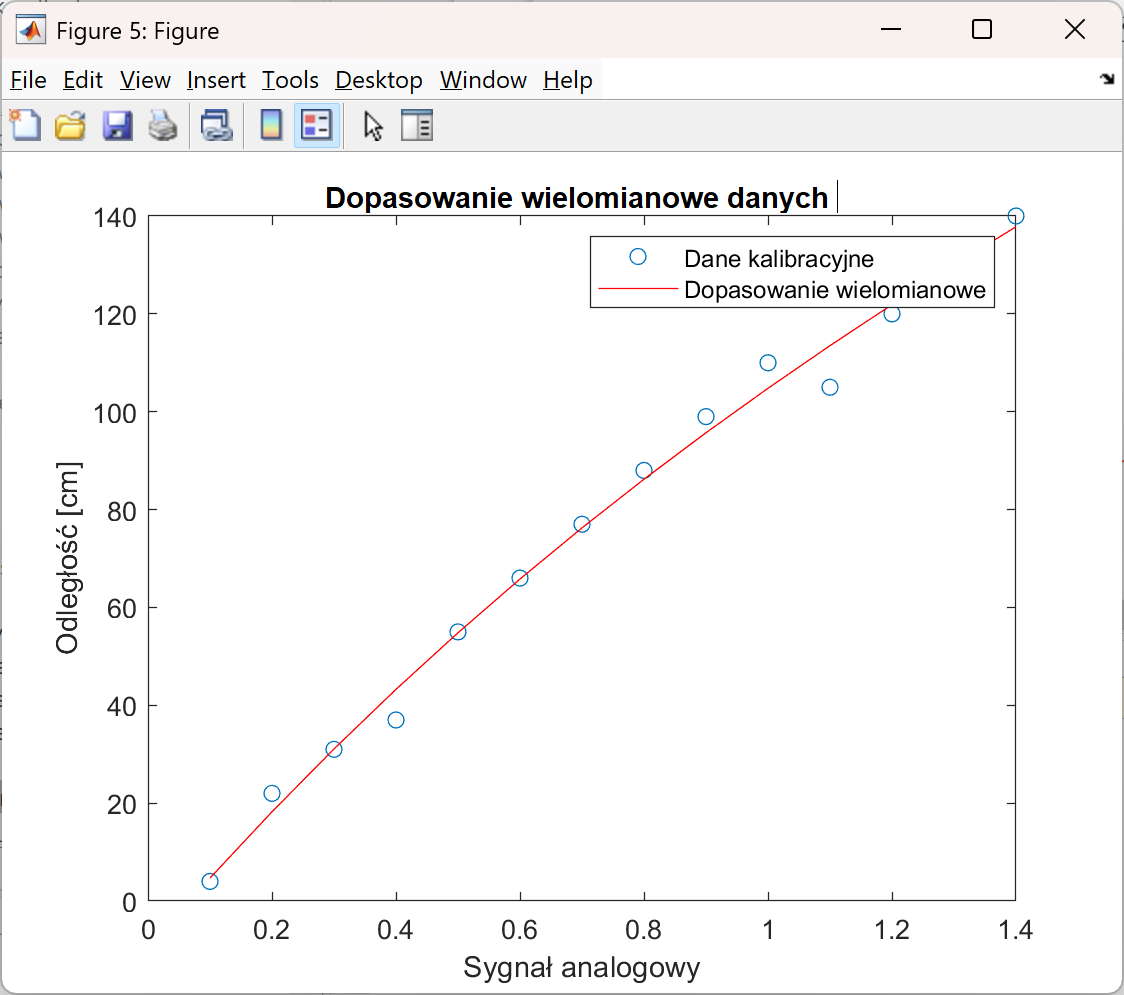

Przykład 